## Aufgabe 2

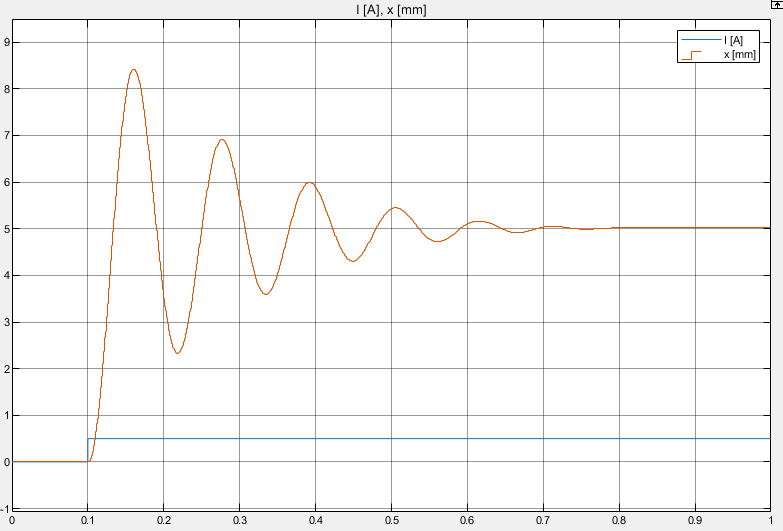

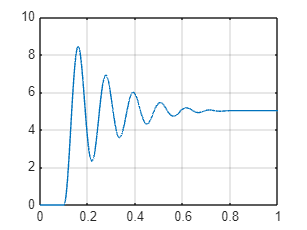

load data_00.mat

figure
plot(data.time, data.signals(2).values), grid on;


Ks_raw = 5.021

Ks_raw = 5.0210

Ks = Ks_raw / 0.5

Ks = 10.0420

Tp = 0.2765 - 0.15665

Tp = 0.1199

d1 = 8.351 - Ks_raw

d1 = 3.3300

d2 = Ks_raw - 2.349

d2 = 2.6720

theta = log(d1 / d2)

theta = 0.2201

D = theta / (sqrt(pi^2 + theta^2))

D = 0.0699

wd = (2 * pi) / Tp

wd = 52.4254

w0 = wd / sqrt(1 - D^2)

w0 = 52.5540

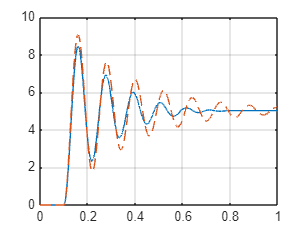


s = tf('s');
G_model_2 = (Ks * w0^2) / (s^2 + 2*D*w0*s + w0^2);
y_mod_1 = lsim(G_model_2, data.signals(1).values, data.time);

figure
plot(data.time, data.signals(2).values), grid on, hold on
plot(data.time, y_mod_1, '--')

### Aufgabe 3

load G_00.mat

Ks_3 = db2mag(20)

Ks_3 = 10

w0_3 = 2 * pi * 7.7

w0_3 = 48.3805

dPeak = db2mag(33 - 20)

dPeak = 4.4668

D_3 = 1 / (2 * dPeak)

D_3 = 0.1119

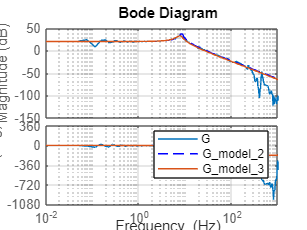


G_model_3 = (Ks_3 * w0_3^2) / (s^2 + 2*D_3*w0_3*s + w0_3^2);

figure
bode(G, G_model_2, '--', G_model_3)
legend

### Aufgabe 4 & 5 & 6

Siehe OneNote

### Aufgabe 7

syms Kd_sym Kp_sym Gv_sym

w_cl = 4 * w0_3

w_cl = 193.5221

D_cl = 1

D_cl = 1


Kd_7 = solve(2 * D_3 * w0_3 + Kd_sym *Ks_3 * w0_3^2 == 2 * D_cl * w_cl, Kd_sym)

$$Kd\_7 = \frac{338649581355008\,\pi }{64339994922442775}-\frac{95270930530763}{205887983751816880}$$

Kd_7 = double(Kd_7)

Kd_7 = 0.0161

Kp_7 = solve((1 + Kp_sym * Ks_3) * w0_3^2 == w_cl^2, Kp_sym)

$$Kp\_7 = \frac{3}{2}$$

Kp_7 = double(Kp_7)

Kp_7 = 1.5000


%Gv = solve((Kp_7 + Kd_7) * Ks_3 * w0_3^2 * Gv_sym == w_cl^2, Gv_sym)
%Gv = double(Gv)
Gv = w_cl^2 / ((Kp_7 + Kd_7 * s) * Ks_3 * w0_3^2)

Gv =
 
       3.745e04
  ------------------
  376.2 s + 3.511e04
 
Continuous-time transfer function.
Model Properties



Tv = double(Kd_7 / Kp_7)

Tv = 0.0107

Tf = double(Tv / 10)

Tf = 0.0011



Gr = Kp_7 * ((Tv * s + 1) / (Tf * s + 1))

Gr =
 
  0.01607 s + 1.5
  ---------------
  0.001072 s + 1
 
Continuous-time transfer function.
Model Properties
